# **Constantes**

C_max    = 15;        %ml/mmHg
C_min    = 0.4;       %ml/mmHg
C_art    = 2;         %ml/mmHg
I_art    = 10^(-4);   %mmHg.s²/ml
p_LA     = 8;         %mmHg
p_RA     = 3;         %mmHg
R_hArt   =  0.1;      %mmHg.s/ml
R_hCap   = 1;         %mmHg.s/ml
R_AV     = 0.1;       %mmHg.s/ml
R_MV     = 10^(-2);   %mmHg.s/ml
V_r      = 5;         %ml
T_ccRef  = 6/7;       %s
T_cc = 6/7;           %s, 60BPM

%T_cc = 1; %able to choose cardiac rythm time

# **Definition  de C_LV et de sa dérivée**

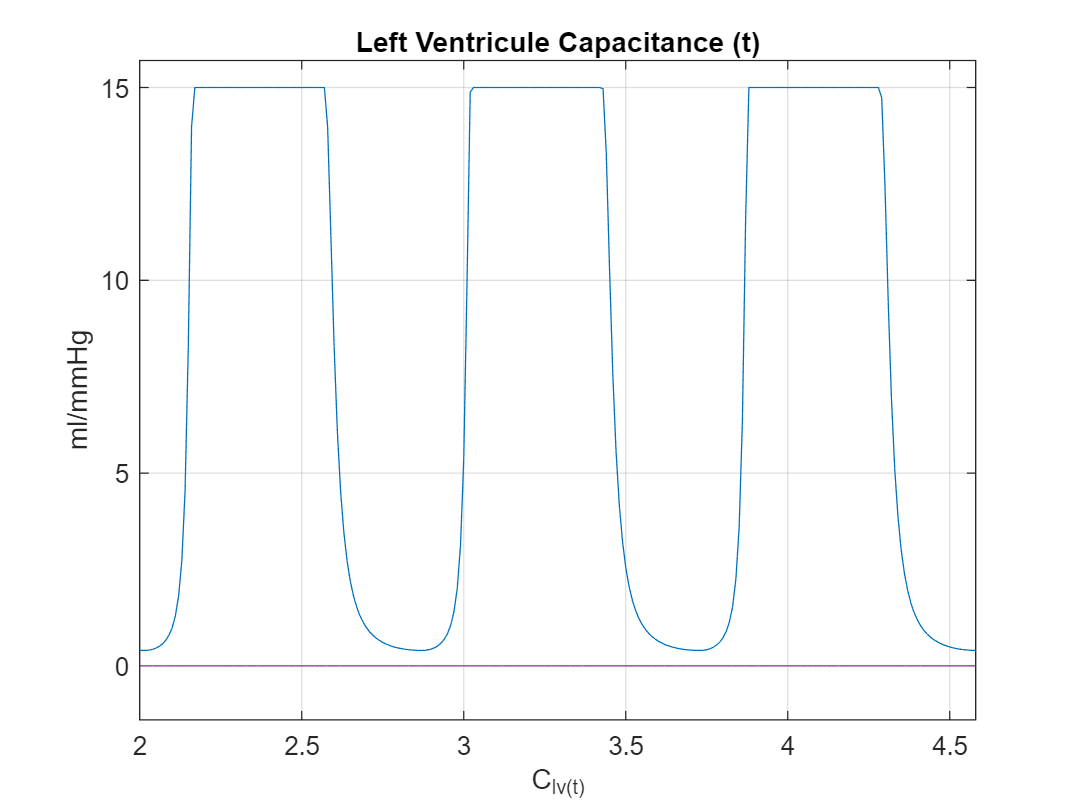

x = 0:1/100:5;
clv = zeros(length(x));
for i=1:length(x)
    clv(i)=capLV(x(i),T_cc,C_min,C_max);
end

plot(x,clv) 
xlabel('C_{lv(t)}')
ylabel('ml/mmHg')
title('Left Ventricule Capacitance (t)')
grid on
hold off
xlim([2.00 4.58])
ylim([-1.4 15.7])

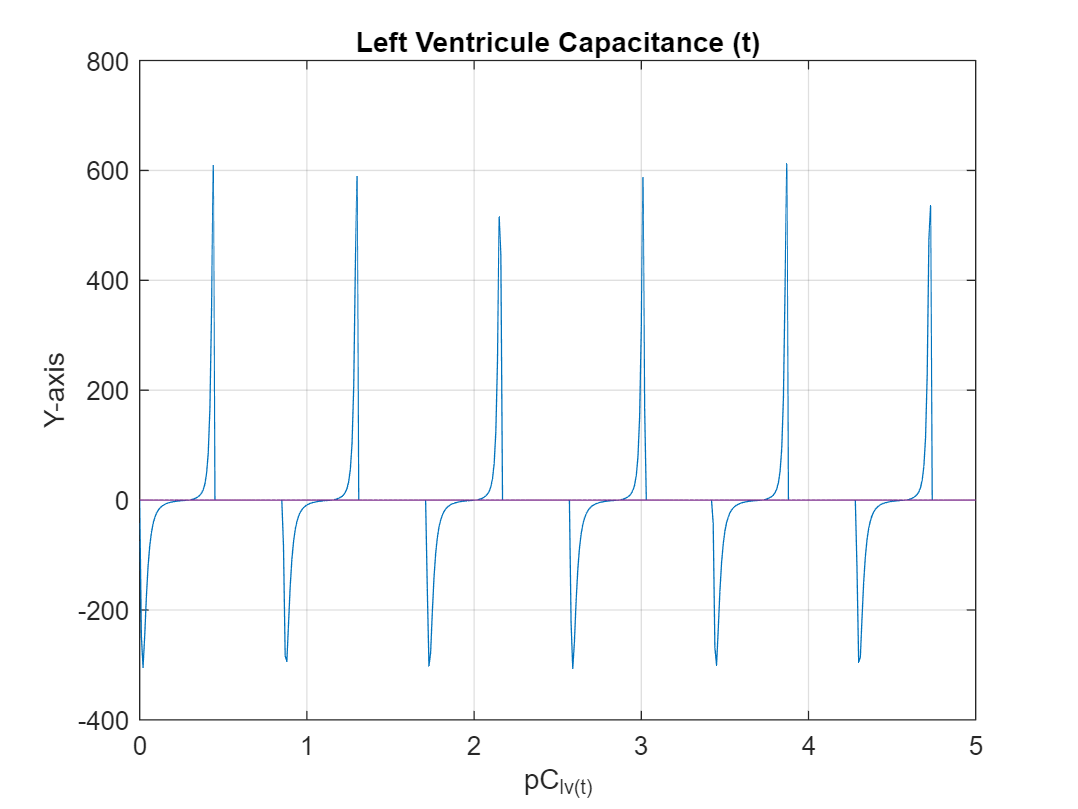

%TODO DÉRIVÉE pour l'instant approx par f(x+dt) -f(x) / x+dx - x

x = 0:1/100:5;
pclv = zeros(length(x));
for i=1:length(x)
    pclv(i)=primeCapLV(x(i),T_cc,C_min,C_max);
end

plot(x,pclv)
xlabel('pC_{lv(t)}')
ylabel('Y-axis')
title('Left Ventricule Capacitance (t)')
grid on
hold off

# **WHOLE CARDIAC SYSTEM**

tspan = [20 50];
y0 = [150 120 70];%À vérifier
[t,y] = ode45(@(t,y) odefcn(t,y,T_cc,C_min,C_max,p_LA,R_MV,I_art,R_hArt,R_hCap,p_RA,R_AV,C_art), tspan, y0);

Compute Other elements of system

Q0 = ((p_LA-y(:,1))./R_MV).*heaviside(p_LA-y(:,1));
Q1 = ((y(:,1)-y(:,3))./R_AV).*heaviside(y(:,1)-y(:,3));

for i=1:length(t)
    V_LV_vec(i) = y(i,1)*capLV(t(i),T_cc,C_min,C_max)-V_r;
end
for i=1:length(t)
    C_LV_vec(i) = capLV(t(i),T_cc,C_min,C_max);
end
C_LV = C_LV_vec.';
V_LV = V_LV_vec.';

# **WHOLE CARDIAC SYSTEM GRAPHICS**

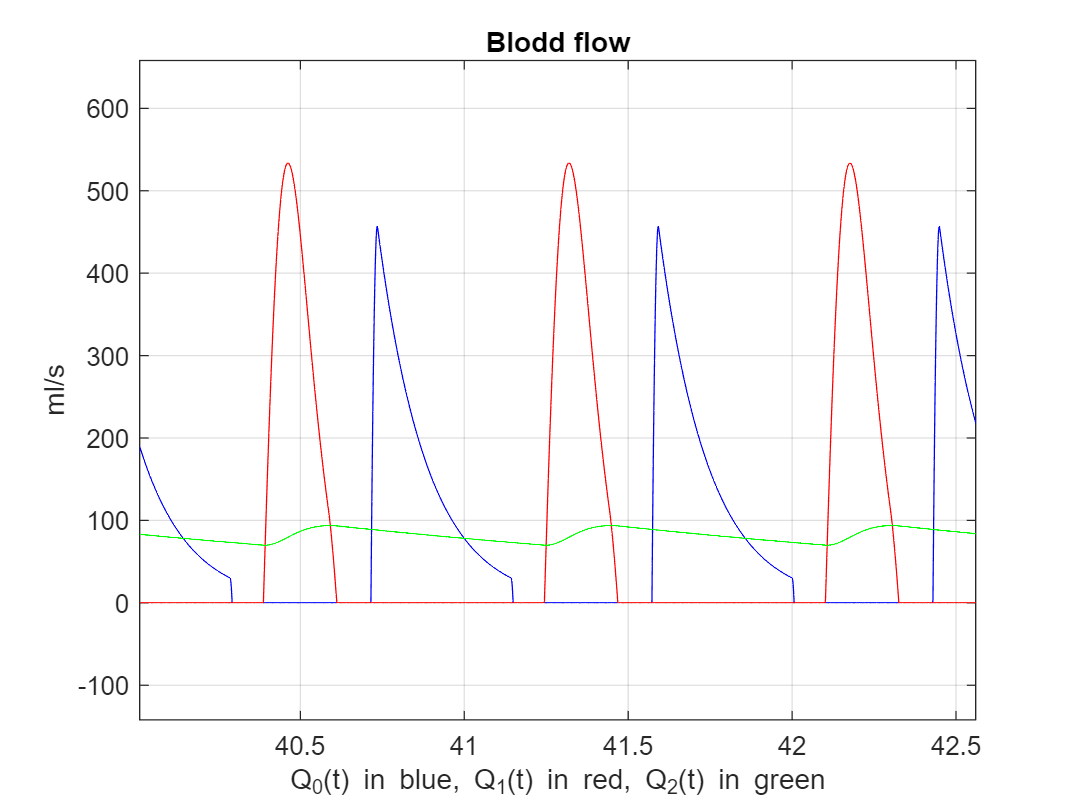

plot(t,Q0,'-b',t,Q1,'-r',t,y(:,2),'-g')
xlabel('Q_{0}(t) in blue, Q_{1}(t) in red, Q_{2}(t) in green')
ylabel('ml/s')
title('Blodd flow')
xlim([40.01 42.56])
ylim([-142 658])
grid on
hold off

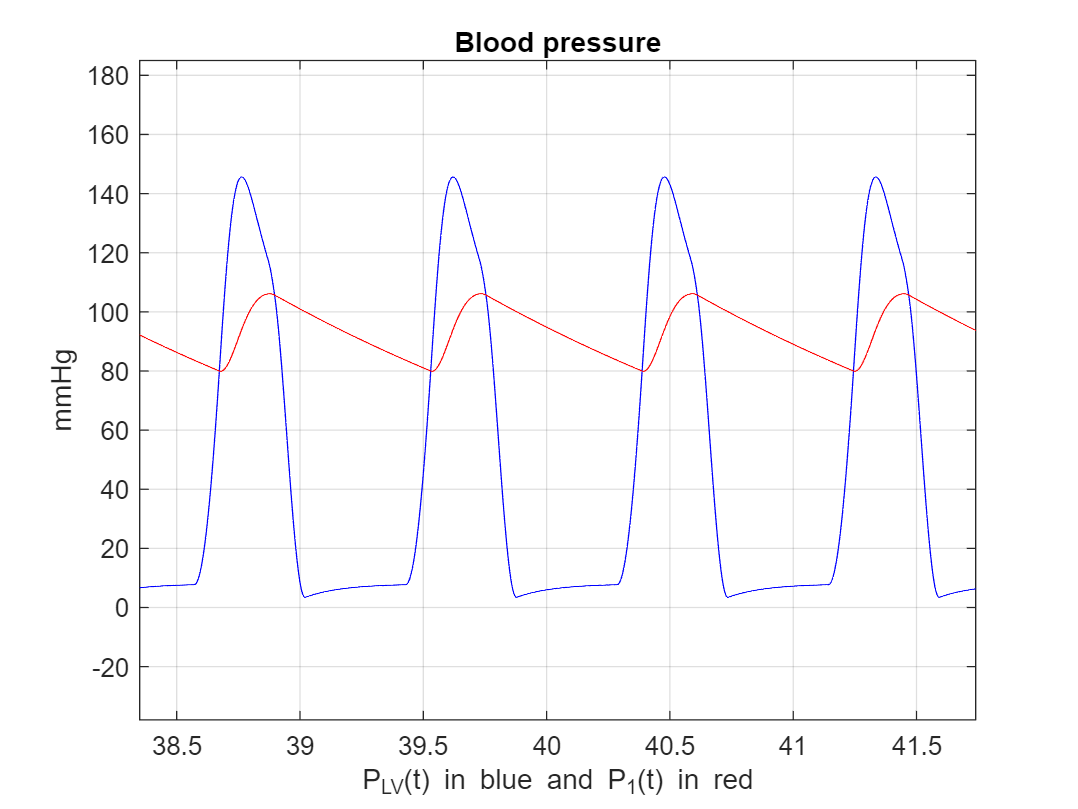

plot(t,y(:,1),'-b',t,y(:,3),'-r')
xlabel('P_{LV}(t) in blue and P_{1}(t) in red')
ylabel("mmHg")
title('Blood pressure')
xlim([38.35 41.74])
ylim([-38 185])
grid on
hold off

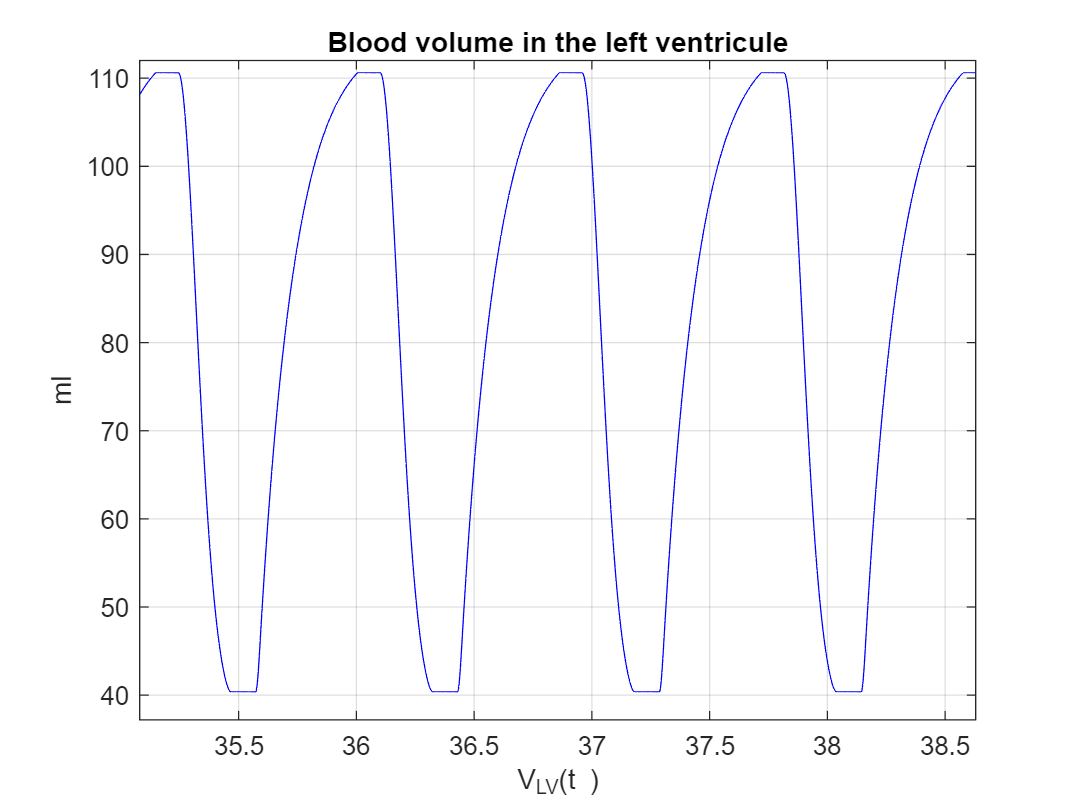

plot(t,V_LV,'-b')
xlabel('V_{LV}(t )')
ylabel('ml')
title('Blood volume in the left ventricule')
grid on
hold off
xlim([35.08 38.63])
ylim([37.2 112.0])

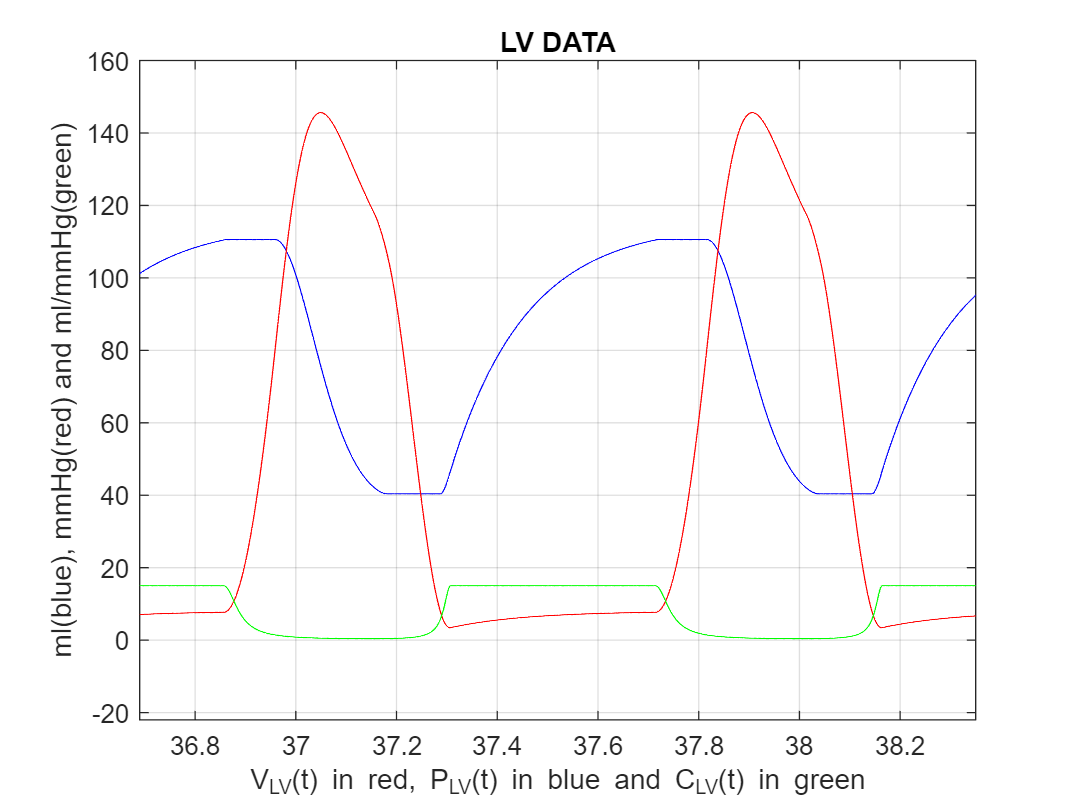

plot(t,V_LV,'-b',t,y(:,1), '-r',t,C_LV,'-g')
xlabel('V_{LV}(t) in red, P_{LV}(t) in blue and C_{LV}(t) in green')
ylabel('ml(blue), mmHg(red) and ml/mmHg(green)')
title('LV DATA')
xlim([36.69 38.35])
ylim([-22 160])
grid on
hold off

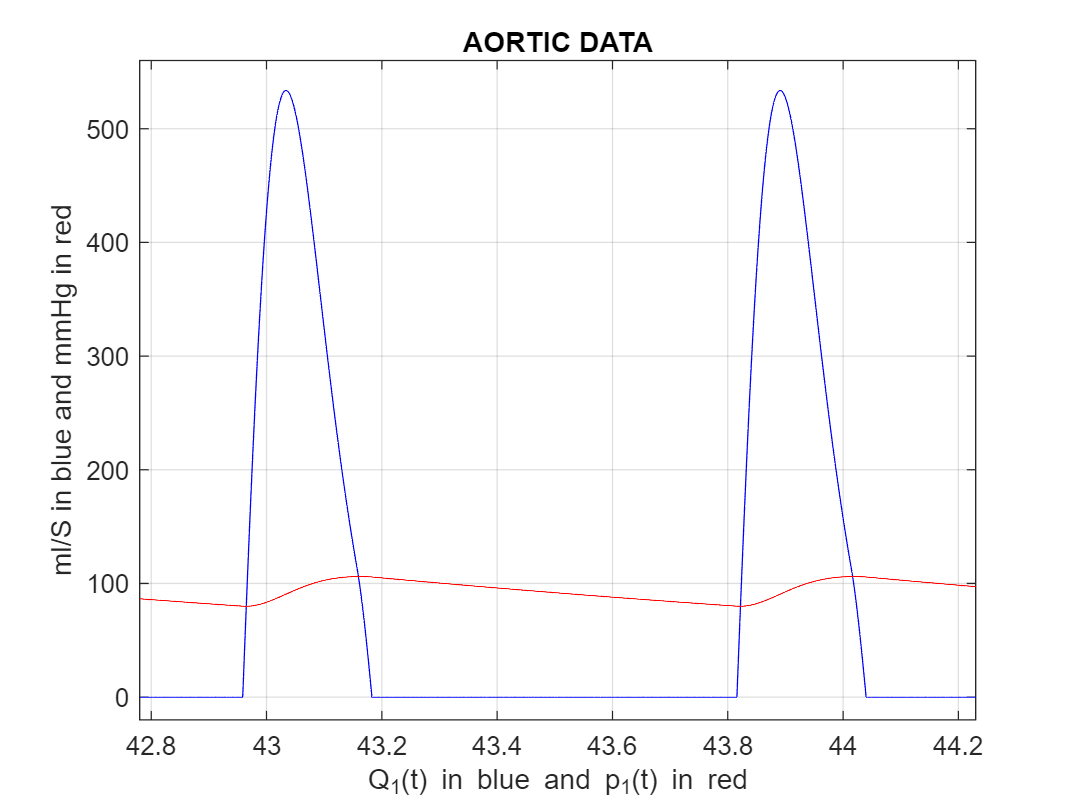

plot(t,Q1,'-b',t,y(:,3), '-r')
xlabel('Q_1(t) in blue and p_1(t) in red')
ylabel('ml/S in blue and mmHg in red')
title('AORTIC DATA')
grid on
hold off
xlim([42.78 44.23])
ylim([-20 560])

# **FUNCTION DEFINTION**

function c_lv = capLV(t,T_cc,C_min,C_max)
    T_ccRef  = 6/7; 
    t_rel = mod(t,T_cc); 
    T_vc = 0.3*(T_cc/T_ccRef);
    T_vr = 0.15*(T_cc/T_ccRef);
    if ((0 < t_rel) && (t_rel <= T_vc))
        ecc = 0.5 * (1 - cos(pi * t_rel / T_vc));
    elseif ((T_vc < t_rel ) && (t_rel  < T_vc + T_vr))
        ecc = 0.5 * (1 + cos(pi* (t_rel -T_vc) / T_vr));
    else 
        ecc = 0;
    end
    c_lv = 1 / ( ( 1/C_min - 1/C_max ) * ecc + 1/C_max);
end

function c_lv_prime = primeCapLV(t,T_cc,C_min,C_max)
    t_else = t+0.000001;
    c_lv_prime = (capLV(t_else,T_cc,C_min,C_max)-capLV(t,T_cc,C_min,C_max))./(t_else-t);
end

function dydt = odefcn(t,y,T_cc,C_min,C_max,p_LA,R_MV,I_art,R_hArt,R_hCap,p_RA,R_AV,C_art)
  dydt = zeros(3,1);
  %eq 56 p_lv = y(1)
  dydt(1) = (-y(1).*primeCapLV(t,T_cc,C_min,C_max)+((p_LA-y(1))/R_MV).*heaviside(p_LA-y(1))-((y(1)-y(3))./R_AV).* heaviside(y(1)-y(3)))./capLV(t,T_cc,C_min,C_max);
  %eq 57  Q2 = y(2)
  dydt(2) =  (y(3)-p_RA-(R_hCap+R_hArt).*y(2))./I_art;
  %eq 58 p1 = y(3)
  dydt(3) = (((y(1)-y(3))./R_AV).*heaviside(y(1)-y(3))-y(2))./C_art;
end
